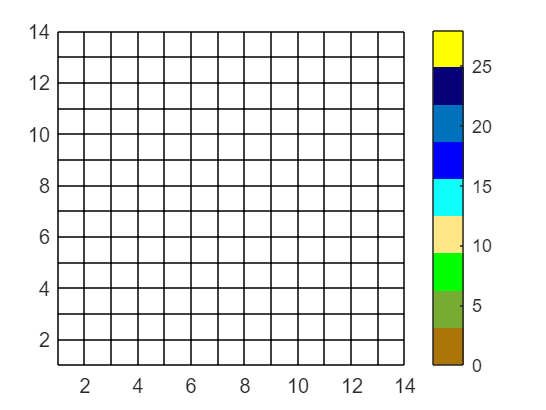

columns = 14;
rows = 14;

limitC = columns - 1;
limitR = rows - 1;

treasureX = randi([1 columns-1]);
treasureY = randi([1 rows-1]); 

map = zeros(rows, columns);

map(map == 0) = NaN;

[x2,y2] = meshgrid(1:columns,1:rows);
taxiMatrix = abs(treasureY - y2(:))+ abs(treasureX - x2(:));

finalMap = reshape(taxiMatrix,rows,columns);

finalMap(treasureY,treasureX) = 500;

cmap = [0.6706 0.4588 0.0392; 0.4667 0.6745 0.1882; 0 1 0;1 0.9059 0.5216;0.0588 1 1; 0 0 1; 0 0.4471 0.7412;0.0314 0 0.4706; 1 1 0];

x = 0;

pcolor(map);
hold on

colormap(cmap);
clim([0 rows*2]);
colorbar;


%pcolor(finalMap)

if(x ~= 0)
    guessX = 10;
    guessY = 1;
    playGame(treasureX,treasureY,map,finalMap,columns,rows,guessX,guessY)
else
    x = x + 1;
end

 


function playGame(tX,tY,m,fm,c,r,gX,gY)
    
    if(gX == tX)&&(gY == tY)
        pcolor(fm)
        disp("You found the treasure!")
    else
        if(gX < c)||(gY < r)
            m(gY,gX) = fm(gY,gX);
            pcolor(m);
            help = "You are " + string(fm(gY,gX)) + " away from the treasure.";
            disp(help);
        end
        disp("Guess again!");
        
    end
end